%生成数据集
Train = fea(trainIdx,:); 
Test = fea(testIdx,:); 
gnd_Train = gnd(trainIdx); 
gnd_Test = gnd(testIdx);
[m,~]=size(Train);
[n,~]=size(Test);
accuracy=0;

%转置数据集 一列为一个图片
fea_Train =Train';
fea_Test =Test';

%归一化处理
meanFace = zeros(size(fea_Train,1),1);
meanFace = mean(fea_Train,2);
A = zeros(size(fea_Train));
A = fea_Train - repmat(meanFace,1,size(fea_Train,2));

%SVD降维
[prinComponents, weightCols] = doPCA(A,20);

for i=1:n%循环测试集照片张数次
%处理测试集
unroll_img = fea_Test(:,i);
fea_TestImg = unroll_img - meanFace;
test_weightCols = prinComponents\fea_TestImg;

%欧几里得距离
[minDist, indexOfClosestMatch] = indexOfClosestColumn(weightCols, test_weightCols);
if(gnd_Train(indexOfClosestMatch)==gnd_Test(i))
    accuracy=accuracy+1;
end

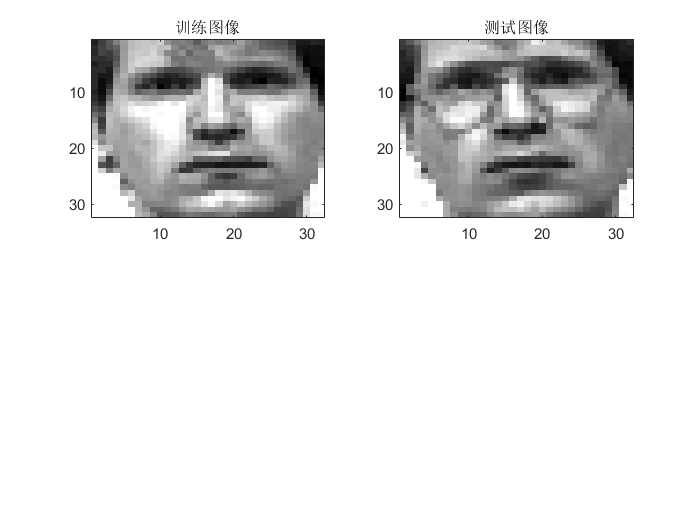

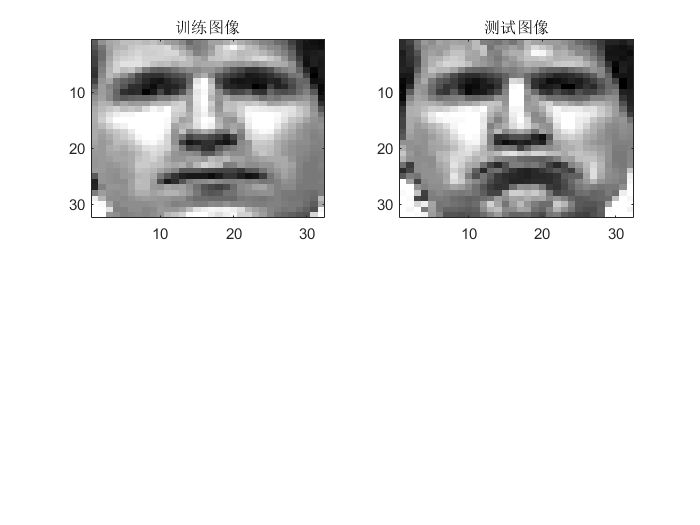

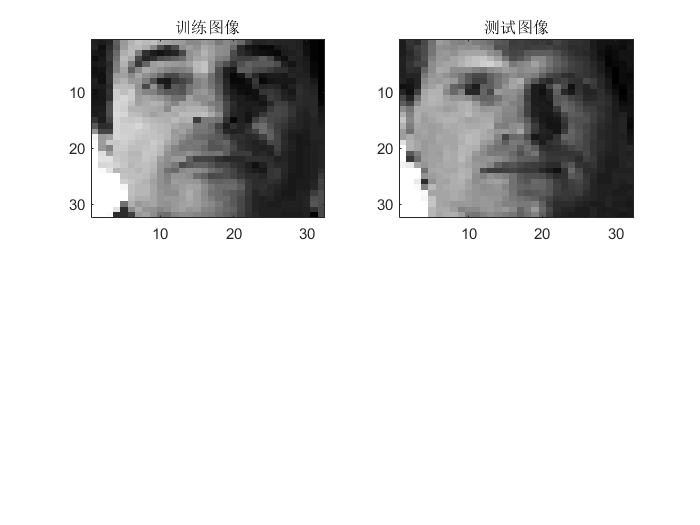

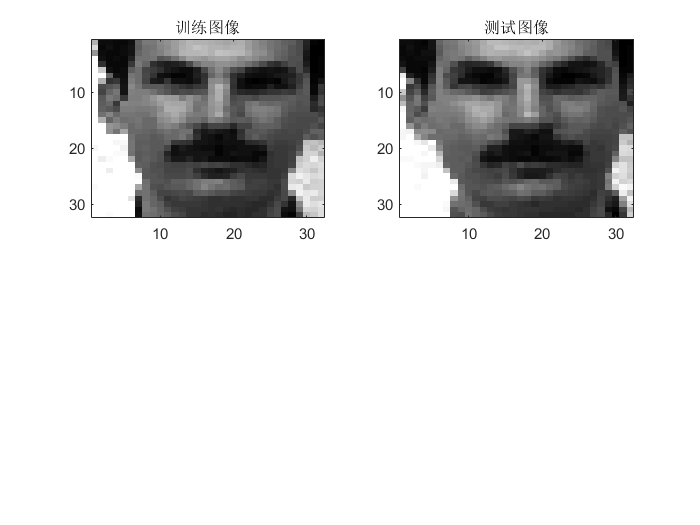

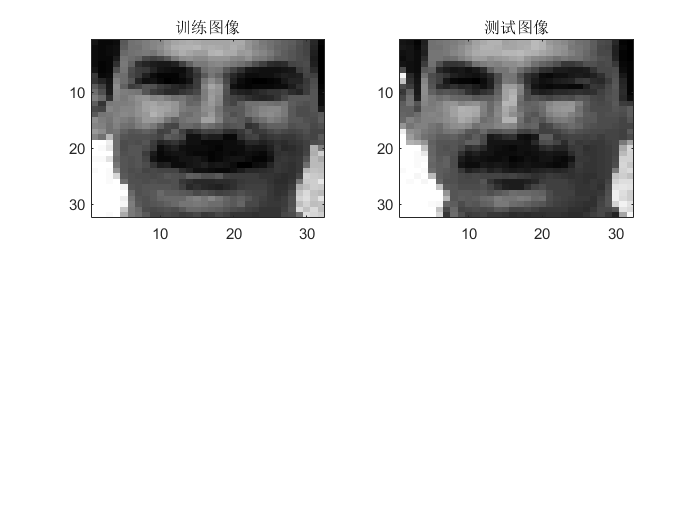

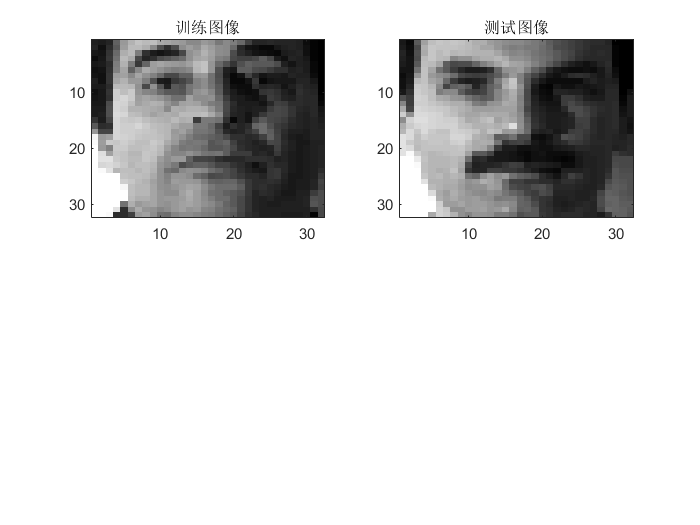

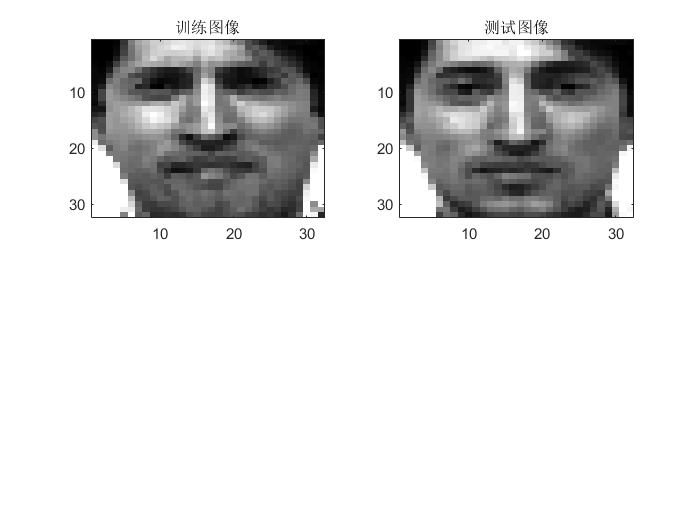

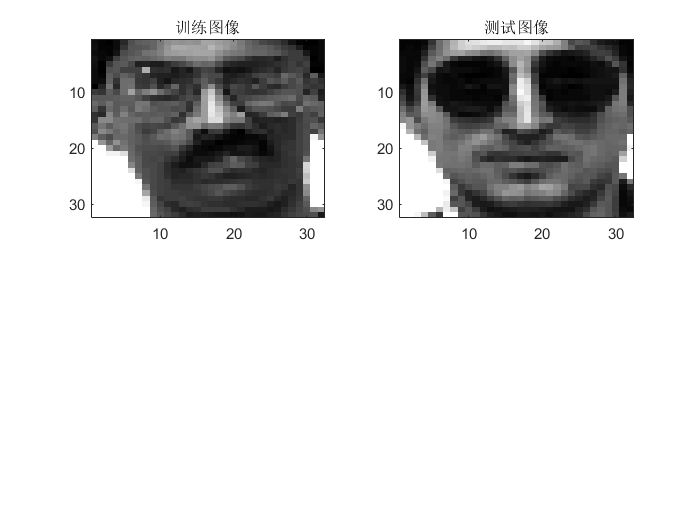

%显示图像
viewFace(fea_Train(:,indexOfClosestMatch), unroll_img);

end

accuracy=accuracy/n

accuracy = 0.6222